snifFft = fft(snifVec);

micFft = fft(micVec);
% snifFft(2:4) = micFft();

diffFft = micFft-snifFft;
newVec2 = ifft(diffFft);

newVec2 = rescale(newVec2,-1,1);

Error using rescale>preprocessInputs (line 83)
First argument must be a real numeric or logical array.

Error in rescale (line 36)
[A, a, b, inputMin, inputMax] = preprocessInputs(A, varargin{:});

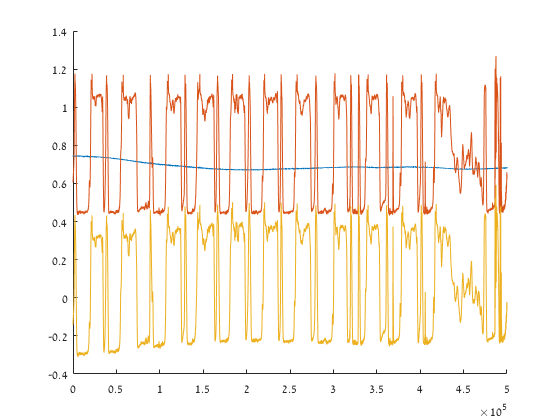

inds = (1:500000)+0;
figure
hold on
plot(snifVec(inds))
plot(micVec(inds))
plot(newVec(inds))
hold off

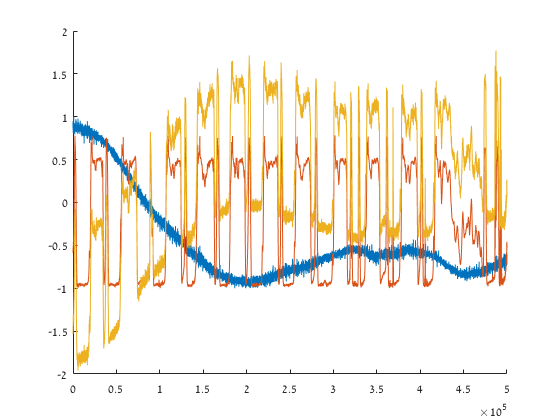

inds = (1:500000)+0;
figure
hold on
plot(snifVec)
plot(micVec)
plot(newVec)
hold off